**Computer Exercise 5.3.1**

The following Program will use an adaptive Simpson's scheme to approximate the integrals of $f(x) = \frac{4}{1 + x^2}$ on $[0, 1]$ and $g(x) = 8(\sqrt{1 - x^2}-x)$ on $\bigg[ 0, \frac{1}{\sqrt{2}}\bigg]$. The corresponding plots of $f(x)$and $g(x)$ will also be displayed where the partitions used in the adaptive scheme will be indicated on the plots. In both cases, the following paramters will be used: $\textit{max\_level} = 4$ and $\varepsilon =  \frac{1}{2}\times 10^{-5}$.

**a) **$4\int_{0}^{1}  \frac{1}{1 + x^2}dx$

%initiate function
f = @(x) 4./((1 + (x.^2)));
%initiate input parameters
a = 0;
b = 1;
err = (0.5)*(10^(-5));
level = 0;
max_level = 4;
result1 = simpson_recur(f, a, b, err, level, max_level);

max level reached: level = 4, result = 0.4974, interval = (0.0000, 0.1250) 

--------------------------------------------------------------------------- 

max level reached: level = 4, result = 0.4825, interval = (0.1250, 0.2500) 

--------------------------------------------------------------------------- 

level = 3, result = 0.9799, interval = (0.0000, 0.2500) 

--------------------------------------------------------------------------- 

error tolerance satisfied: level = 3, result = 0.8747, interval = (0.2500, 0.5000) 

--------------------------------------------------------------------------- 

level = 2, result = 1.8546, interval = (0.0000, 0.5000) 

--------------------------------------------------------------------------- 

error tolerance satisfied: level = 3, result = 0.7194, interval = (0.5000, 0.7500) 

--------------------------------------------------------------------------- 

error tolerance satisfied: level = 3, result = 0.5676, interval = (0.7500, 1.0000) 

-------

***The above output is used to assist in constructing the following plot:***

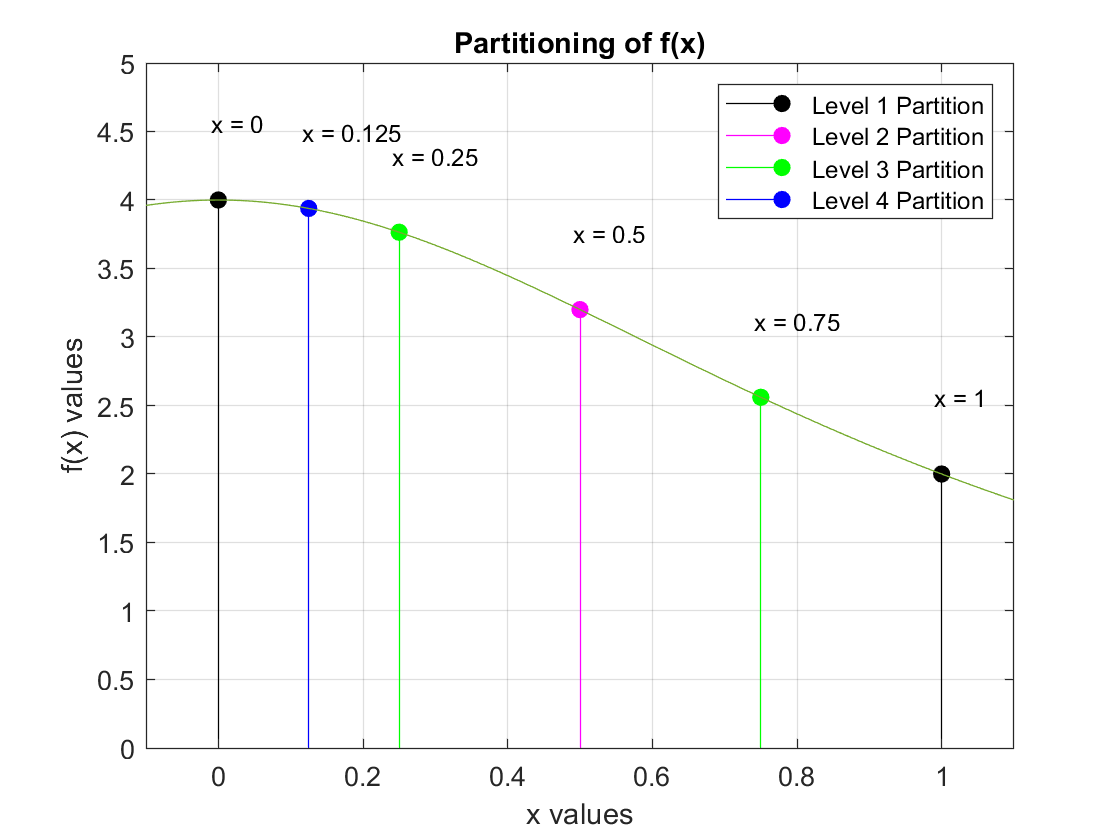

%plotting code
xvals1 = linspace(a,b, (2^(max_level-3))+1);
yvals1 = f(xvals1);
xvals2 = linspace(a,b, (2^(max_level-2))+1 );
yvals2 = f(xvals2);
xvals3 = linspace(a,b, (2^(max_level-1))+1 );
xvals3(xvals3 == 0.875) = [];
xvals3(xvals3 == 0.625) = [];
xvals3(xvals3 == 0.375) = [];
yvals3 = f(xvals3);
xvals4 = linspace(a,b, (2^(max_level-3))+1);
xvals4(xvals4 == a) = [];
xvals4(xvals4 == b) = [];
yvals4 = f(xvals4);

clf
stem4 = stem(xvals3, yvals3, 'filled', "Color", 'blue');
grid on
hold on
stem3 = stem(xvals2, yvals2, 'filled', "Color", 'green');
stem1 = stem(xvals1, yvals1, 'filled', "Color", 'black');
stem2 = stem(xvals4, yvals4, 'filled', "Color", 'magenta');
xfit = linspace(a-0.1,b+0.1);
yfit = f(xfit);
plot(xfit, yfit,  'DisplayName', 'Curve Fit')

legend([stem1, stem2, stem3, stem4], ...
    {'Level 1 Partition', 'Level 2 Partition', 'Level 3 Partition', 'Level 4 Partition'})

xlim([-0.1 1.1])
ylim([0 5])
lbl_dwny = 0.14*max(yvals3);
lbl_dwnx = 0.01*max(xvals3);
%label the individual points
for i = 1:length(xvals3)
     % Label the points with the corresponding 'x' value
     txt = ['x = ', num2str(round(xvals3(i), 3, 'significant'))];%, ',', ' ' , ...
         %num2str(round(yvals(i), 2, 'significant')), ')'];
     
     text(xvals3(i)-lbl_dwnx,yvals3(i)+lbl_dwny,txt, ...
         'FontSize',9);
end
title('Partitioning of f(x)')
xlabel('x values')
ylabel('f(x) values')
hold off

Evaluated Partitions In the Recursive Simpson Scheme for $f(x)$:

Level 1: $\text{Partition} = \{ [0, 1]\}$

Level 2: $\text{Partition} = \{ [0, 0.5], [0.5,1]\}$

Level 3: $\text{Partition} = \{ [0, 0.25], [0.25,0.5], [0.5, 0.75], [0.75, 1]\}$

Level 4: $\text{Partition} = \{ [0, 0.125], [0.125, 0.25]\}$

We see that only the first interval of level 3 is paritioned into level 4. From the above output of the recusive Simpson algorithm, we can indeed see that this is the case since three out of four of the level 3 intervals indicate that the error tolerance has been satisfied.

fprintf('Approximate value for the integral: %5.4f', result1)

Approximate value for the integral: 3.1416

The approximation of the integral for $f(x)$ turns out to be an approximation of $\pi$. Of course, this is to be expected since analytically: $4\int_{0}^{1}  \frac{1}{1 + x^2}dx = 4[arctan(1) - arctan(0)] = 4\bigg(\frac{\pi}{4}\bigg) = \pi$.

**b) **$8\int_{0}^{1/{\sqrt{2}}} (\sqrt{1 - x^2}-x)dx$

%initiate function
g = @(x) 8.*(sqrt(1 - x.^2) - x);
%initiate input parameters
a = 0;
b = 1/(sqrt(2));
err = (0.5)*(10^(-5));
level = 0;
max_level = 4;
result2 = simpson_recur(g, a, b, err, level, max_level);

error tolerance satisfied: level = 3, result = 1.2818, interval = (0.0000, 0.1768) 

--------------------------------------------------------------------------- 

error tolerance satisfied: level = 3, result = 0.9865, interval = (0.1768, 0.3536) 

--------------------------------------------------------------------------- 

level = 2, result = 2.2683, interval = (0.0000, 0.3536) 

--------------------------------------------------------------------------- 

error tolerance satisfied: level = 3, result = 0.6411, interval = (0.3536, 0.5303) 

--------------------------------------------------------------------------- 

max level reached: level = 4, result = 0.1721, interval = (0.5303, 0.6187) 

--------------------------------------------------------------------------- 

max level reached: level = 4, result = 0.0601, interval = (0.6187, 0.7071) 

--------------------------------------------------------------------------- 

level = 3, result = 0.2322, interval = (0.5303, 0.7071) 

-------

***The above output is used to assist in constructing the following plot:***

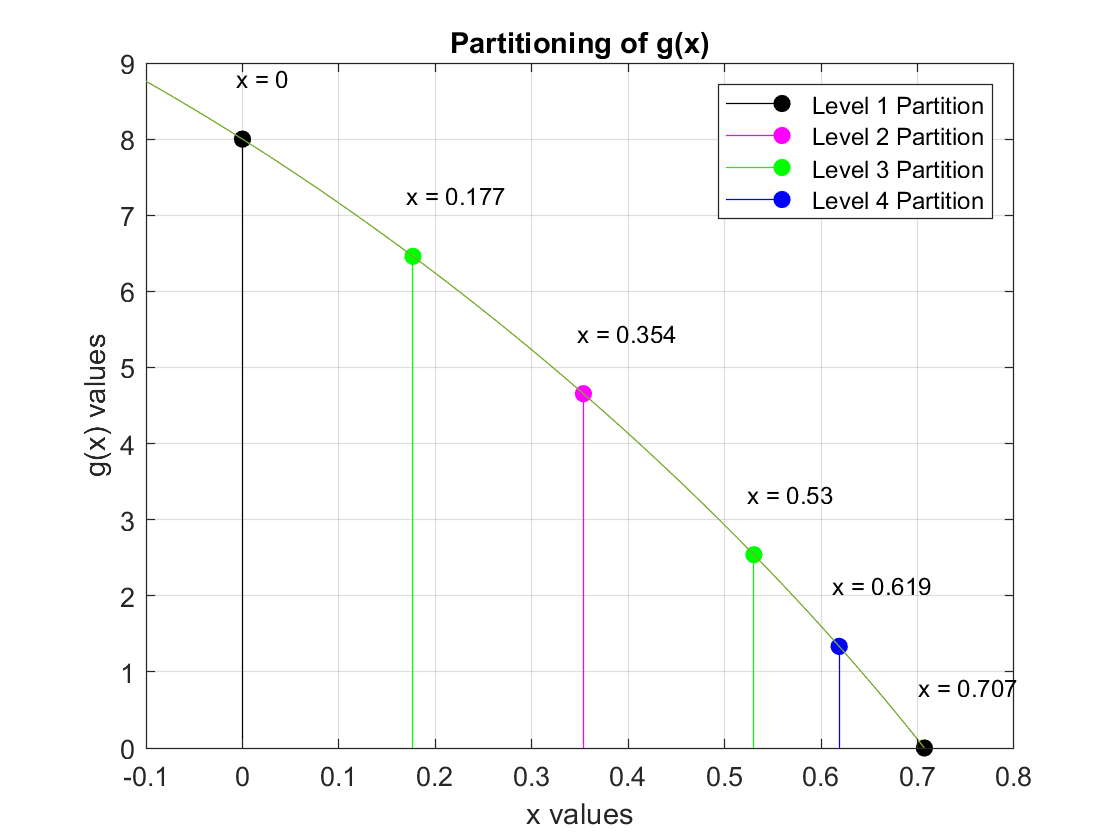

%plotting code
xvals5 = linspace(a,b, (2^(max_level-1))+1 );
xvals5(2) = [];
xvals5(3) = [];
xvals5(4) = [];
yvals5 = g(xvals5);
xvals6 = linspace(a,b, (2^(max_level-2))+1 );
yvals6 = g(xvals6);
xvals7 = linspace(a,b, (2^(max_level-3))+1 );
yvals7 = g(xvals7);
xvals8 = linspace(a,b, (2^(max_level-3))+1 );
xvals8(1) = [];
xvals8(2) = [];
yvals8 = g(xvals8);

clf
stem5 = stem(xvals5, yvals5, 'filled', "Color", 'blue');
hold on
grid on
xlim([-0.1 0.8])
ylim([0 9])

stem6 = stem(xvals6, yvals6, 'filled', "Color", 'green');
stem7 = stem(xvals7, yvals7, 'filled', "Color", 'black');
stem8 = stem(xvals8, yvals8, 'filled', "Color", 'magenta');

xfit = linspace(a-0.1,b+0.1);
yfit = g(xfit);
plot(xfit, yfit,  'DisplayName', 'Curve Fit')
lbl_dwny = 0.1*max(yvals5);
lbl_dwnx = 0.01*max(xvals5);
%label the individual points
for i = 1:length(xvals5)
     % Label the points with the corresponding 'x' value
     txt = ['x = ', num2str(round(xvals5(i), 3, 'significant'))];%, ',', ' ' , ...
         %num2str(round(yvals(i), 2, 'significant')), ')'];
     
     text(xvals5(i)-lbl_dwnx,yvals5(i)+lbl_dwny,txt, ...
         'FontSize',9);
end

legend([stem7, stem8, stem6, stem5], ...
    {'Level 1 Partition', 'Level 2 Partition', 'Level 3 Partition', 'Level 4 Partition'})
title('Partitioning of g(x)')
xlabel('x values')
ylabel('g(x) values')
hold off

Evaluated Partitions In the Recursive Simpson Scheme for  $g(x)$:

Level 1: $\text{Partition} = \{ [0, 0.707]\}$

Level 2: $\text{Partition} = \{ [0, 0.354], [0.354,0.707]\}$

Level 3: $\text{Partition} = \{ [0, 0.177], [0.177,0.354], [0.354, 0.53], [0.53, 0.707]\}$

Level 4: $\text{Partition} = \{ [0.53, 0.619], [0.619, 0.707]\}$

We see that only the final interval of level 3 is partitioned into level 4 intervals which means error condidtions were satisfied for the other intervals of level 3. Indeed, this can be seen in the output of the recursive simpson algorithm.

fprintf('Approximate value for the integral: %5.4f', result2)

Approximate value for the integral: 3.1416

We see that the integral for $g(x)$is also an approximation of $\pi$ and is hence, equal to that of $f(x)$.

function result = simpson_recur(f, a, b, err, level, max_level)
    level = level + 1; %increment level upon recursion
    h = b - a;
    c = (a + b)/2;
    simpson_1 = (h/6)*(f(a) + 4*f(c) + f(b));
    d = (a + c)/2;
    e = (c + b)/2;
    simpson_2 = (h/12)*(f(a)+ 4*f(d) + 2*f(c) + 4*f(e) + f(b));
    %recursion and output
    if level >= max_level
        result = simpson_2;
        fprintf(['max level reached: level = %d, result = %4.4f, ' ...
            'interval = (%4.4f, %4.4f) \n\n'], level, result, a, b)
        fprintf(['-------------------------------------' ...
            '-------------------------------------- \n\n'])
    else
        if abs(simpson_1 - simpson_2) < 15*err
            result = simpson_2 + (simpson_2 - simpson_1)/15;
            fprintf(['error tolerance satisfied: level = %d, result = %4.4f, ' ...
                'interval = (%4.4f, %4.4f) \n\n'], level, result, a, b)
            fprintf(['-----------------------------------' ...
                '---------------------------------------- \n\n'])
        else
            %left recursion
            left_simpson = simpson_recur(f, a, c, err/2, level, max_level);
            %right recursion
            right_simpson = simpson_recur(f, c, b, err/2, level, max_level);
            result = left_simpson + right_simpson;
            fprintf('level = %d, result = %4.4f, interval = (%4.4f, %4.4f) \n\n', ...
                level, result, a, b)
            fprintf(['---------------------------------' ...
                '------------------------------------------ \n\n'])
        end        
    end 
end